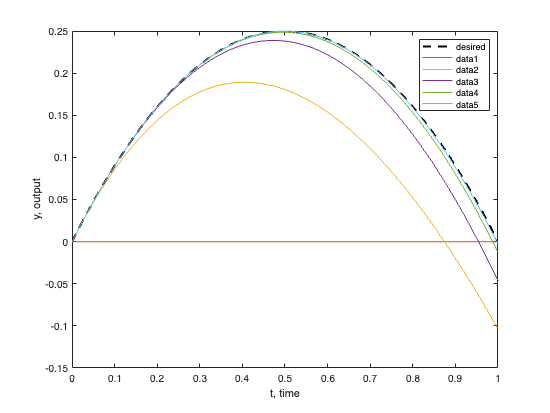

% arimoto1984

% FIRST EXAMPLE (ref. Figure 4)

% define timeseries
dt = 0.001;
t = 0:dt:1;

% desired output
yd = t.*(1-t);

% initial input
v = 0*t;

% predeclare output
y = 0*t;

% set up figure with desired output
figure;
plot(t,yd,'--k','LineWidth',2);
legend('desired');
xlabel('t, time');
ylabel('y, output');
hold on;

% i-loop: iteration
for i = 1:5

    % j-loop: timestep
    for j = 1:length(t)
        tj = t(j);
        myInt = 0;

        % k-loop: numerical integral
        for k = 1:j
            tk = t(k);
            myInt = myInt + exp( -1 * ( tj-tk ) ) * v(k) * dt;
        end

        y(j) = myInt;
    end
    
    % iterative learning control algorithm
    e  = yd - y;
    ed = [0 diff(e)/dt];
    v  = v + ed;

    % check output convergence
    plot(t,y);
end

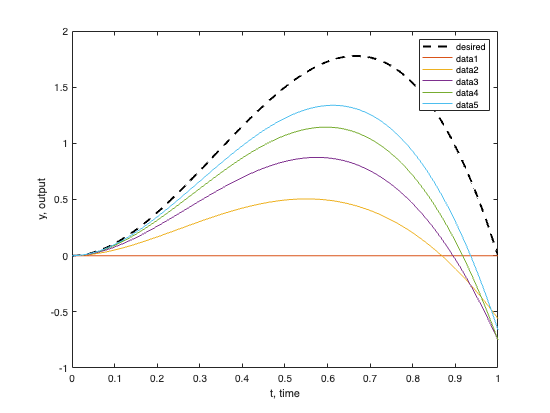

% SECOND EXAMPLE (ref. Figures 7 and 8)

% retain timeseries

% state-space model
A = [0 1; -1 -2];
B = [0; 1];
C = [0 1];

% desired output (velocity)
yd = 12 .* t.^2 .* (1 - t);
% NB: this implies x0 = [0 0]

% betterment constant
% Gamma = 1.0;
Gamma = 0.5;

% initial input
u = 0*t;

% predeclare output
y = 0*t;

% set up figure with desired output
figure;
plot(t,yd,'--k','LineWidth',2);
legend('desired');
xlabel('t, time');
ylabel('y, output');
hold on;

% i-loop: iteration
for i = 1:5

    % j-loop: timestep
    for j = 1:length(t)
        tj = t(j);
        myInt = 0;  % since x0 = [0 0]

        % k-loop: numerical integral
        for k = 1:j
            tk = t(k);
            myInt = myInt + C * expm( A * ( tj-tk ) ) * B * u(k) * dt;
        end

        y(j) = myInt;
    end
    
    % iterative learning control algorithm
    e  = yd - y;
    ed = [0 diff(e)/dt];
    u  = u + Gamma*ed;

    % check output convergence
    plot(t,y);
end